# Entrenando redes neuronales

Debe contar con los Adds-on

- `Computer Vision Toolbox`

- `Image Processing Toolbox`

- `Computer Vision Toolbox Model for YOLO v4 Object Detection`

- `Deep Learning Toolbox`

## `Tutorial disponible en Matlab`

[https://la.mathworks.com/help/vision/ref/yolov4objectdetector.html](https://la.mathworks.com/help/vision/ref/yolov4objectdetector.html) 

[https://la.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v4-deep-learning.html](https://la.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v4-deep-learning.html) 

Seguiremos los pasos sugeridos en el tutorial con la red neuronal YOLO... Los cuales indican lo siguiente:

### Pasos para ejecución de YOLO

Creamos el detector de objetos YOLO v4  usando una red preentrenada.

name = "tiny-yolov4-coco";
detector = yolov4ObjectDetector(name);

Mostramos las caracteristicas del detector.

disp(detector)  

Mostramos la arquitectura del detector.

analyzeNetwork(detector.Network)

Cargamos una imagen de prueba y ejecutamos el detector

img = imread("highway.png");
[bboxes,scores,labels] = detect(detector,img)

Se muestra la imagen resultante

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)


### Entendiendo la salida de la red neuronal

Cargamos una imagen de prueba en la carpeta donde estamos trabajando

img = imread("PersonaCoche2.png");
[bboxes,scores,labels] = detect(detector,img)

%bboxes : [x y ancho alto]
%scores : Porcentaje de probabilidad de detección
%labels : Etq

Display the detection results.

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)
hold on

%Sobre las cajas
x = bboxes(:,1);
y = bboxes(:,2);
w = bboxes(:,3);
h = bboxes(:,4);
%plot(x,y,'o',MarkerSize=10,MarkerFaceColor='b')
plot(x+w/2,y+h/2,'o',MarkerSize=10,MarkerFaceColor='b')


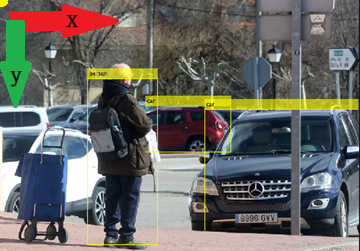

Fig. Marco de referencia de la imagen

Se requieren entonces dos cosas

- Reentrenar la red neuronal para reconocer objetos que nos interesen y no esten en la lista.

- Conocer las parámetros intrínsecos y extrínsecos de la cámara para transformar pixeles en mm.

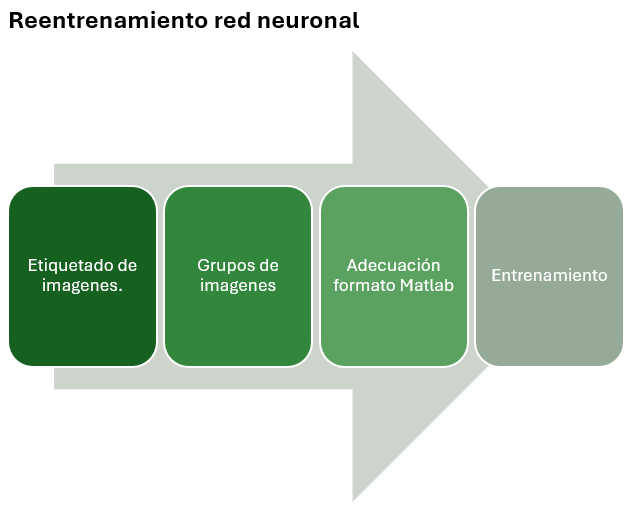

### Etiquetando imagenes: Image labeler 

[https://la.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html](https://la.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html) 

Image labeler es una aplicación en Matlab que nos ayuda a etiquetar imagenes, usulamente esta actividad consume bastantes recursos de tiempo.

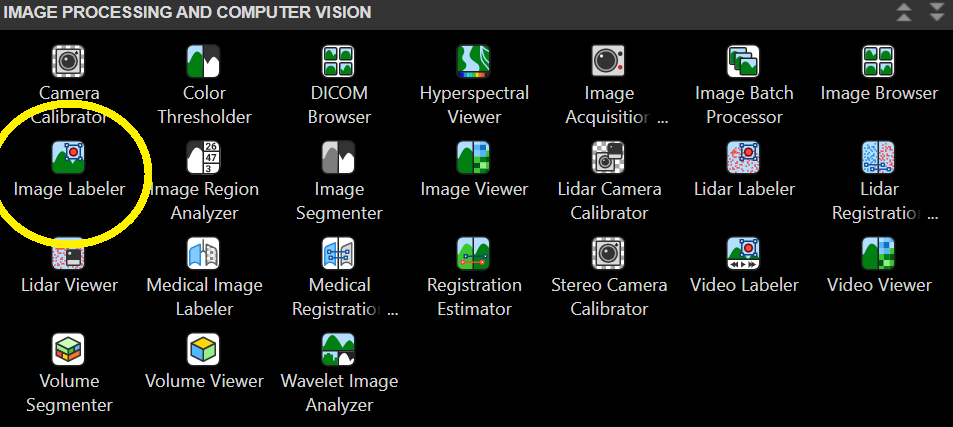

%Con la siguiente instrucción podrás también acceder al image labeler.
imageLabeler

1. Aquí importaremos las imagenes.

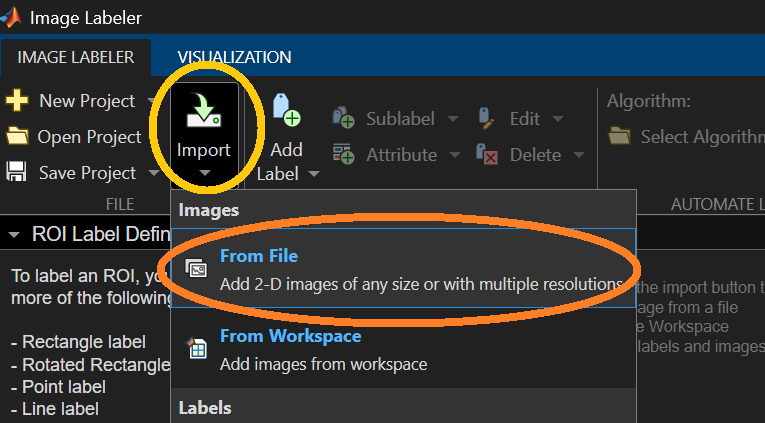

2. Agregamos etiquetas

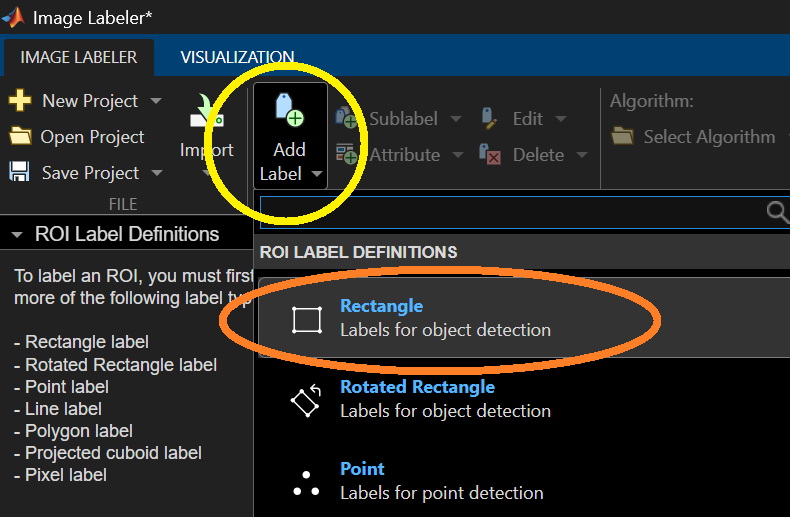

3. Seleccionamos imagenes

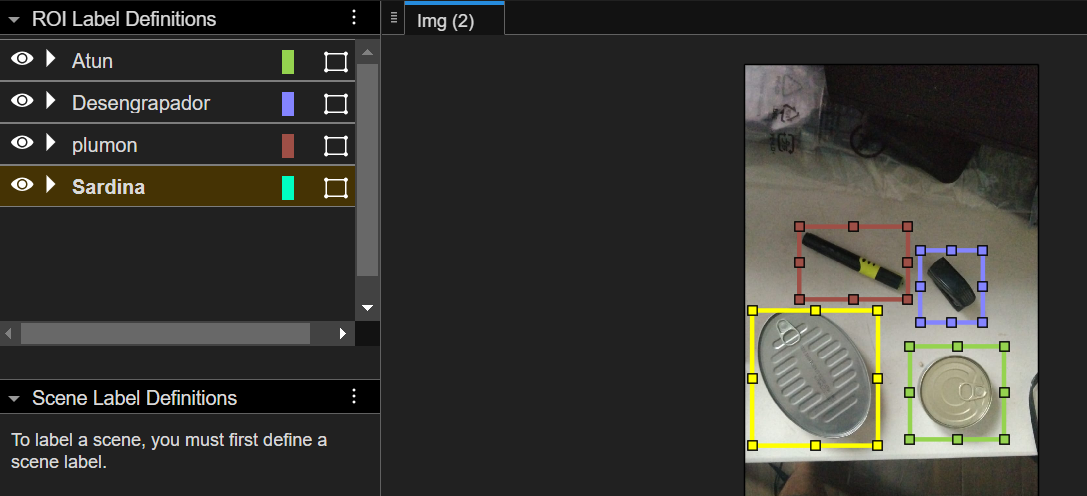

4. Exportamos tabla de direcciones y etiquetas.

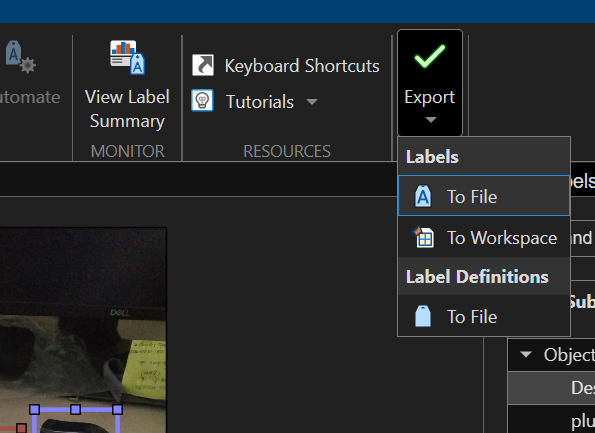

### Reentrenamiento de Red Neuronal

[https://la.mathworks.com/help/vision/ug/object-detection-using-yolov4-deep-learning.html](https://la.mathworks.com/help/vision/ug/object-detection-using-yolov4-deep-learning.html) 

Para entrenar la red neuronal, necesitamos.

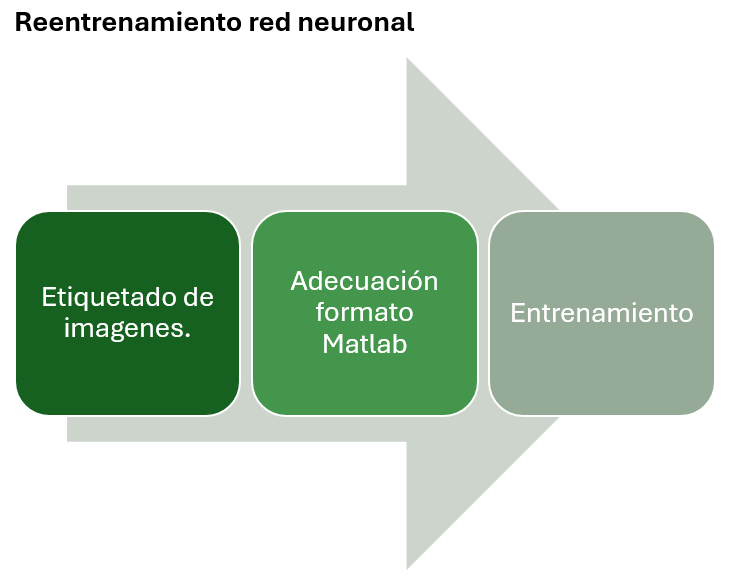

1. Registrar las direcciones de nuestras imagenes así como el contenido de cada imagen

data = load("ObjetosCadiEntrenamiento.mat")

data = struct with fields:
    gTruth: [1×1 groundTruth]


direccion = data.gTruth.DataSource.Source

direccion = 51×1 cell array
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\1.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\2.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\3.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\4.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\5.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\6.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\7.png' }
    {'C:\User

cajas = data.gTruth.LabelData

cajas = 51×5 table
        Cubo            Lata          Botella             Spam               Plumon      
    ____________    ____________    ____________    ________________    _________________

    {9×4 double}    {5×4 double}    {6×4 double}    {3×4 double    }    {[161 108 70 36]}
    {8×4 double}    {4×4 double}    {5×4 double}    {3×4 double    }    {2×4 double     }
    {8×4 double}    {4×4 double}    {6×4 double}    {3×4 double    }    {2×4 double     }
    {9×4 double}    {5×4 double}    {6×4 double}    {3×4 double    }    {3×4 double     }
    {8×4 double}    {4×4 double}    {6×4 double}    {6×4 double    }    {2×4 double     }
    {8×4 double}    {4×4 double}    {7×4 double}    {3×4 double    }    {2×4 double     }
    {8×4 double}    {4×4 double}    {6×4 double}    {3×4 double    }    {3×4 double     }



mi_dataset = [direccion cajas]

mi_dataset = 51×6 table
                                                                    Var1                                                                        Cubo            Lata          Botella             Spam               Plumon      
    ____________________________________________________________________________________________________________________________________    ____________    ____________    ____________    ________________    _________________

    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\1.png' }    {9×4 double}    {5×4 double}    {6×4 double}    {3×4 double    }    {[161 108 70 36]}
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterr

mi_dataset.Properties.VariableNames(1) = {'imageFilename'}

mi_dataset = 51×6 table
                                                               imageFilename                                                                    Cubo            Lata          Botella             Spam               Plumon      
    ____________________________________________________________________________________________________________________________________    ____________    ____________    ____________    ________________    _________________

    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\CADi2025\ImagenesReto\1.png' }    {9×4 double}    {5×4 double}    {6×4 double}    {3×4 double    }    {[161 108 70 36]}
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterr

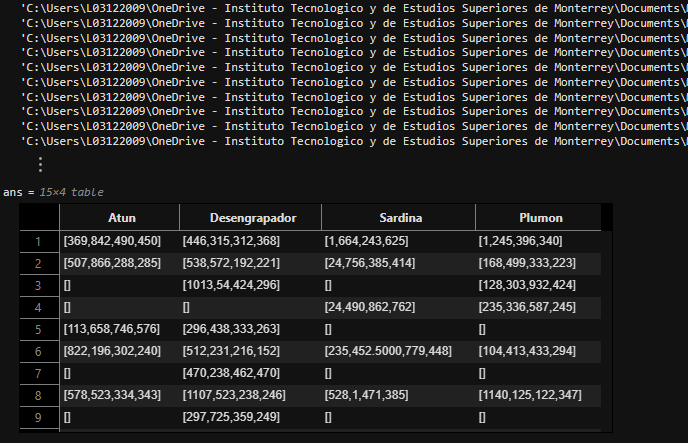

Fig. Información de ubicación de archivos y contenido de imagenes

2. Se generan bloques de entrenamiento, validación y prueba.

% Establecer la semilla del generador de números aleatorios para reproducibilidad
rng("default");

% Se asume que personasDataset ya está cargado en el espacio de trabajo

% Generar una permutación aleatoria de los índices de las filas del dataset
shuffledIndices = randperm(height(mi_dataset));

% Calcular el número de datos para el conjunto de entrenamiento (60% del total)
idx = floor(0.7 * length(shuffledIndices));

% Seleccionar los índices para el conjunto de entrenamiento
trainingIdx = 1:idx;
trainingDataTbl = mi_dataset(shuffledIndices(trainingIdx), :);

% Calcular los índices para el conjunto de validación (10% del total)
validationIdx = idx + 1 : idx + 1 + floor(0.2 * length(shuffledIndices));
validationDataTbl = mi_dataset(shuffledIndices(validationIdx), :);

% Asignar los índices restantes al conjunto de prueba
testIdx = validationIdx(end) + 1 : length(shuffledIndices);
testDataTbl = mi_dataset(shuffledIndices(testIdx), :);

% Ahora, trainingDataTbl, validationDataTbl y testDataTbl contienen
% los datos divididos en entrenamiento (70%), validación (20%) y prueba (10%).

4. Creamos los paquetes para cargar las fotos durante el entrenamiento

lista = string(mi_dataset.Properties.VariableNames(2:end))

lista = 1×5 string array
    "Cubo"    "Lata"    "Botella"    "Spam"    "Plumon"



imdsTrain = imageDatastore(trainingDataTbl{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,lista));

imdsValidation = imageDatastore(validationDataTbl{:,"imageFilename"});
bldsValidation = boxLabelDatastore(validationDataTbl(:,lista));

imdsTest = imageDatastore(testDataTbl{:,"imageFilename"});
bldsTest = boxLabelDatastore(testDataTbl(:,lista));


5. Combinamos la información

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

validateInputData(trainingData);

'validateInputData' is used in the following examples:
  Object Detection Using Custom Training Loop
  Object Detection Using YOLO v3 Deep Learning
  Object Detection Using YOLO v4 Deep Learning
  Prune Filters in a Detection Network Using Taylor Scores

validateInputData(validationData);
validateInputData(testData);

6. Validamos información

data = read(trainingData);

I = data{1};
bbox = data{2};
label = data{3};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = insertObjectAnnotation(annotatedImage, "Rectangle", bbox, label, ...
    TextBoxOpacity=0.9, FontSize=18);
figure
imshow(annotatedImage)
reset(trainingData)


7. Ajustamos y aumentamos el dataset

rng("default")
augmentedTrainingData = transform(trainingData,@augmentData);

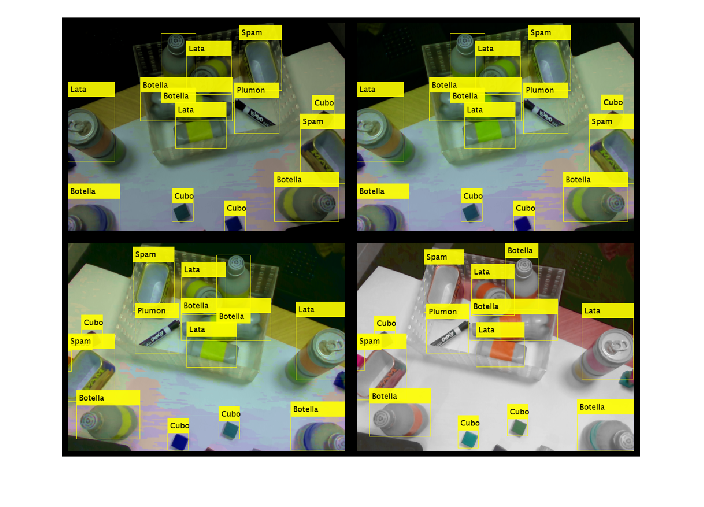

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    augmentedData{k} = insertObjectAnnotation(augmentedData{k},"rectangle",data{2},data{3},TextBoxOpacity=0.9,FontSize=18);

    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

8. Precargamos la red neuronal

inputSize = [416 416 3]

inputSize =    416   416     3


lista

lista = 1×5 string array
    "Cubo"    "Lata"    "Botella"    "Spam"    "Plumon"


trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors)

anchors =     29    21
    46    47
   129    81
    79    47
   416   416
    69    83


meanIoU = 0.7390


area = anchors(:, 1).*anchors(:,2)

area =          609
        2162
       10449
        3713
      173056
        5727


[~,idx] = sort(area,"descend")

idx =      5
     3
     6
     4
     2
     1



anchors = anchors(idx,:)

anchors =    416   416
   129    81
    69    83
    79    47
    46    47
    29    21


anchorBoxes = {anchors(1:3,:)
    anchors(4:6,:)}

anchorBoxes = 2×1 cell array
    {3×2 double}
    {3×2 double}



detector = yolov4ObjectDetector("tiny-yolov4-coco",lista,anchorBoxes,InputSize=inputSize);


9. Entrenamos la red neuronal

options = trainingOptions("adam", ...
    GradientDecayFactor=0.9, ...          % Factor de decaimiento del gradiente (para optimización ADAM)
    SquaredGradientDecayFactor=0.999, ... % Factor de decaimiento del cuadrado del gradiente
    InitialLearnRate=0.001, ...           % Tasa de aprendizaje inicial
    LearnRateSchedule="none", ...         % Sin ajuste programado de la tasa de aprendizaje
    MiniBatchSize=10, ...                 % Tamaño del mini-lote (batch) por iteración
    L2Regularization=0.0005, ...          % Regularización L2 para evitar sobreajuste
    MaxEpochs=100, ...                     % Número máximo de épocas de entrenamiento
    DispatchInBackground=true, ...        % Cargar datos en segundo plano para mejorar eficiencia
    ResetInputNormalization=true, ...     % Restablecer la normalización de entrada en cada iteración
    Shuffle="every-epoch", ...            % Mezclar los datos en cada época
    VerboseFrequency=4, ...              % Mostrar información de entrenamiento cada x iteraciones
    ValidationFrequency=20, ...         % Evaluar con datos de validación cada 1000 iteraciones
    CheckpointPath=tempdir, ...           % Guardar puntos de control temporales
    ValidationData=validationData, ...    % Usar los datos de validación previamente definidos
    OutputNetwork="best-validation-loss"); % Guardar el modelo con la menor pérdida en validación+

    [detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);

Computing Input Normalization Statistics.

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* Cubo
* Lata
* Botella
* Spam
* Plumon

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________
      1          1         00:00:19        0.001         5.3795           84.085    
      1          4         00:01:03        0.001         40.128                     
      2          8         00:01:39        0.001         24.472                     
      3         12         00:02:13        0.001         18.366                     
      4         16         00:02:43        0.001        

10. Probamos la red neuronal.

    
reset(testData);
data = read(trainingData);
img = data{1};

[bboxes, scores, labels] = detect(detector, img)
img = insertObjectAnnotation(img,"rectangle",bboxes,labels);

bboxes = 5×4 single matrix
  101.4046  190.1165  173.5299  233.1128
  167.0182    1.0000  166.6097  206.1303
  204.3448  134.0458  159.7815  122.8327
  349.7441  169.4922   76.1682   74.1791
    1.0000  241.3921   85.0871   87.0801


scores = 5×1 single column vector
    0.9898
    0.9344
    0.9820
    0.9763
    0.9920


labels = 5×1 categorical array
     Botella 
     Lata 
     Lata 
     Cubo 
     Cubo 


figure
imshow(img)

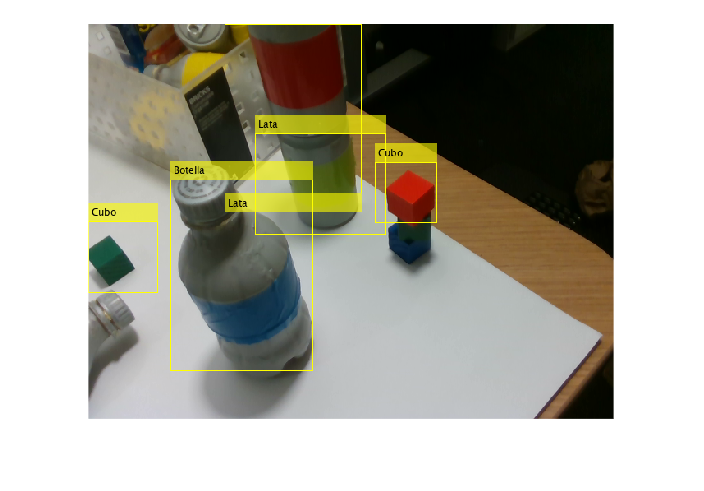

function data = preprocessData(data,targetSize)

    for num = 1:size(data,1)
        I = data{num,1};
        imgSize = size(I);
        bboxes = data{num,2};
        I = im2single(imresize(I,targetSize(1:2)));
        scale = targetSize(1:2)./imgSize(1:2);
        bboxes = bboxresize(bboxes,scale);
        data(num,1:2) = {I,bboxes};
    end
end

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
    data = cell(size(A));
    for num = 1:size(A,1)
        I = A{num,1};
        bboxes = A{num,2};
        labels = A{num,3};
        sz = size(I);

        if numel(sz) == 3 && sz(3) == 3
            I = jitterColorHSV(I,...
                contrast=0.0,...
                Hue=0.1,...
                Saturation=0.2,...
                Brightness=0.2);
        end
    
        % Randomly flip image.
        tform = randomAffine2d(XReflection=true,Scale=[1 1.1]);
        rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
        I = imwarp(I,tform,OutputView=rout);
    
        % Apply same transform to boxes.
        [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
        labels = labels(indices);
    
        % Return original data only when all boxes are removed by warping.
        if isempty(indices)
            data(num,:) = A(num,:);
        else
            data(num,:) = {I,bboxes,labels};
        end
    end
end